s0_add_paths;

## Get the image and filters

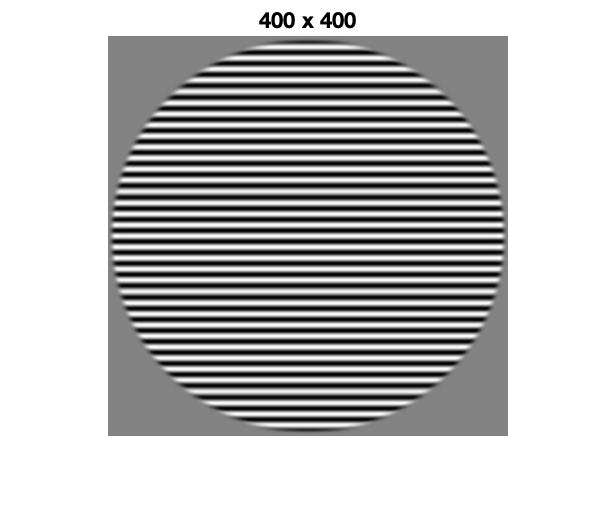

ep = 5;
label = 10; 

fname = sprintf('stimuli-dataset%02d_orig.mat', ds); 
path  = fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli');
% preprocess
stimuli  = double(stimuli);
stimuli  = stimuli./255 - .5;
[Gabor_c, Gabor_s] = get_Filters(stimuli, ds, filter_cpd);
stim = stimuli(:, :, ep, label);
imshow(stim, [])
title(sprintf('%d x %d', size(stim,1), size(stim,2)))

## The contrast energy

% define the orientation
o        = linspace(0,pi, 9); % orientation
thetavec = o(1:end-1); % exclude the pi deg
nO       = length(thetavec);
labelVec = 1:size(stimuli, 4);

% get the size of the pad image
numpix  = size(stimuli,1);
re_szs  = [150, 225, 150, 150]; 
support = 6;

% ----  Adjusted by IB
fovs    = 12.5 * [1, 3/2, 1, 1]; % deg (the second data set had a larger field of view than the others)
fov     = fovs(ds);
pixperdeg = numpix / fov;
ppc     = round(pixperdeg./0.75); % pixels per cycle
padsize = ppc .* support; % need to check
% -----

re_sz   = re_szs(ds) + ceil(padsize*re_szs(ds)/numpix)*2;

% get the stimulus and pad the stimulus
stimulus = stimuli(:, :, ep, label);
padstimulus = zeros(numpix+padsize*2, numpix+padsize*2);
padstimulus(padsize+(1:numpix), padsize+(1:numpix)) = stimulus;
stimulus = padstimulus;

% filter and get the CONTRAST of the image
% dims: X x Y x ori
conEnergy = Icontrast(stimulus, Gabor_c, Gabor_s);

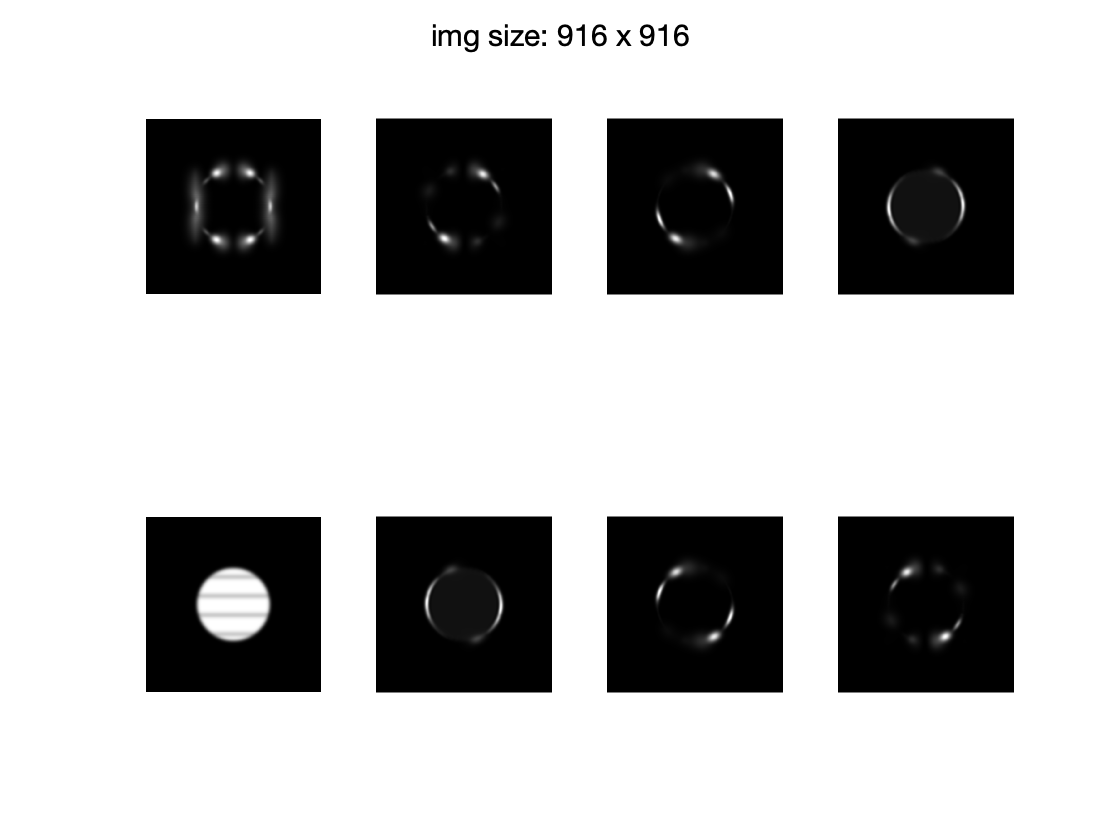

figure();
for i=1:8
    subplot(2, 4, i)
    imshow(conEnergy(:, :, i), [])
end
sgtitle(sprintf('img size: %d x %d', size(conEnergy, 1), size(conEnergy, 2)))

## The new edge filter

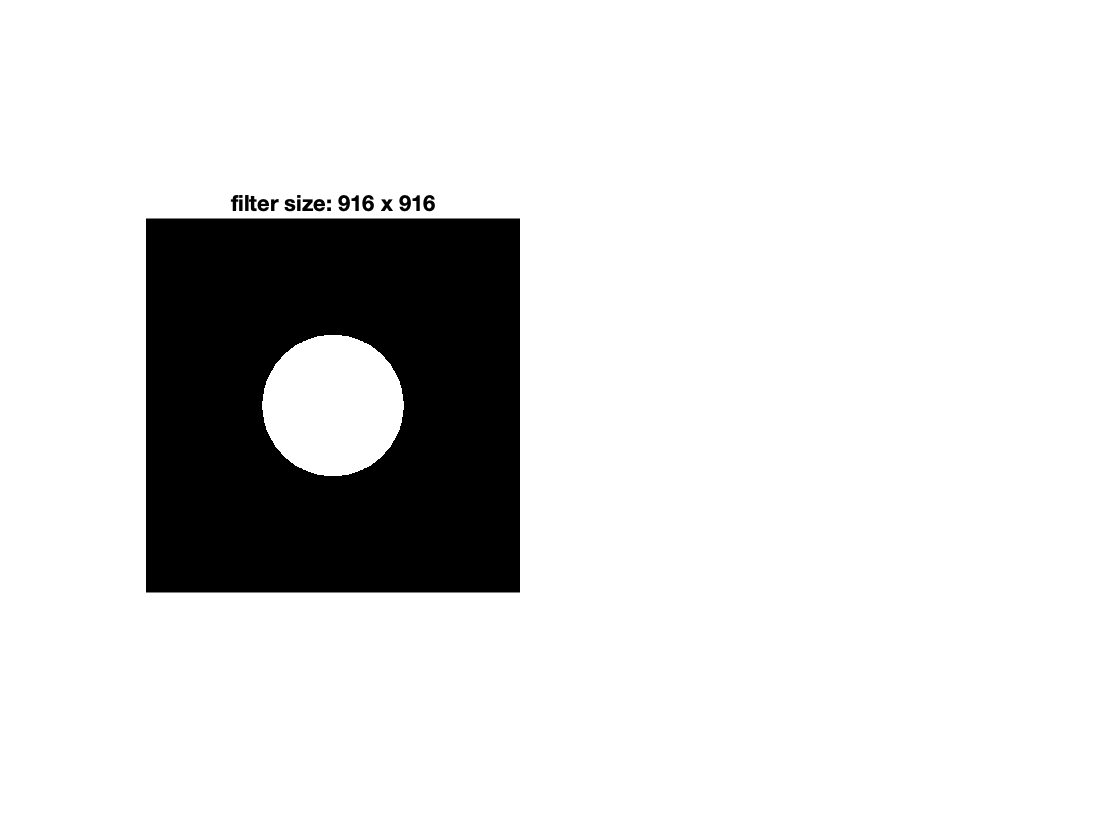

figure(); 
subplot(1, 2, 1)
w = gen_disk(size(conEnergy, 1), numpix);
imshow(w, [])
title(sprintf('filter size: %d x %d', size(w, 1), size(w, 2)))

## After edge filter

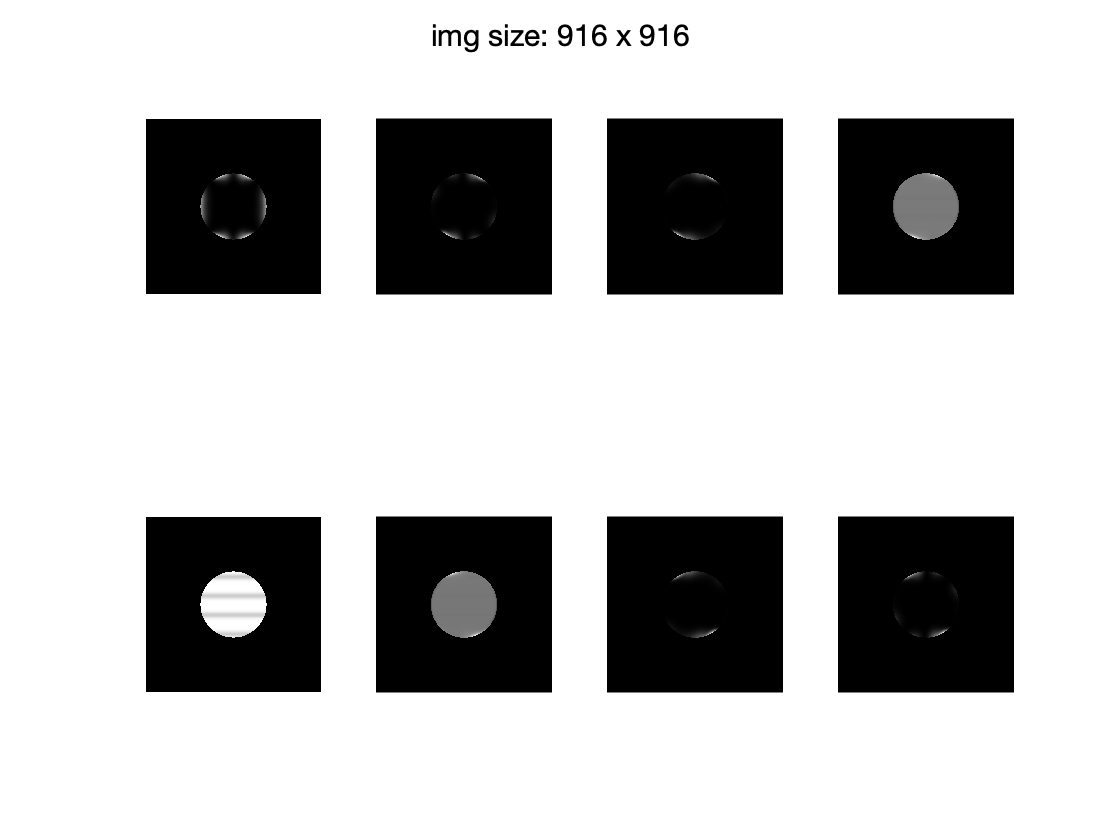

E = conEnergy.*w;
maxE = max(E(:));
minE = min(E(:));
figure();
for i=1:8
    subplot(2, 4, i)
    imshow(E(:, :, i), [])
end
sgtitle(sprintf('img size: %d x %d', size(E, 1), size(E, 2)))